# Mars Rover: Final Project

Follow the instructions provided in the course to complete your final project. 

### Load the images

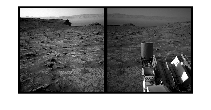

% Load the images
fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

montage({movingImg, fixedImg},"BorderSize",[10 10])

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

% Register the two images
%reg = registerMarsImages(movingImg, fixedImg)
reg = registerMarsImages2(movingImg, fixedImg)

reg = struct with fields:
     FixedMatchedFeatures: [81×1 SURFPoints]
    MovingMatchedFeatures: [81×1 SURFPoints]
           Transformation: [1×1 projective2d]
          RegisteredImage: [1024×1024 uint8]
            SpatialRefObj: [1×1 imref2d]


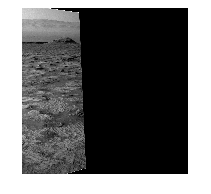

figure; imshow(reg.RegisteredImage)

### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

%tforms(2) = projtform2d();
%tforms(2) = rigid2d();
%tforms(1) = reg.Transformation;
tforms = zeros(2, 3, 3);
tforms(1,:,:) = reg.Transformation.T;
tforms(2,:,:) = eye(3);

for i = 1:2           
    [xlim(i,:),ylim(i,:)] = outputLimits(projective2d(squeeze(tforms(i,:,:))),[1 1024],[1 1024]);
end
% Find the minimum and maximum output limits 
xMin = min(xlim(:))

xMin = single
-1.0622e+03

xMax = max(xlim(:))

xMax = single
1024

yMin = min(ylim(:))

yMin = single
-167.2821

yMax = max(ylim(:))

yMax = single
1.3957e+03


% Width and height of panorama.
imgWidth  = round(xMax - xMin)

imgWidth = single
2086

imgHeight = round(yMax - yMin)

imgHeight = single
1563


% Initialize the "empty" panorama.
%panorama = zeros([imgHeight, imgWidth, 3],"uint8");
panorama = zeros([imgHeight, imgWidth],"uint8");

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

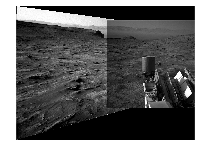

blender = vision.AlphaBlender("Operation","Binary mask","MaskSource","Input port");  
panoramaView = imref2d([imgHeight imgWidth],[xMin xMax],[yMin yMax]);
imgs{1} = movingImg;
imgs{2} = fixedImg;
% Create the panorama
for i = 1:2
   
    % Transform img into the panorama
    warpedImage = imwarp(imgs{i},projective2d(squeeze(tforms(i,:,:))),"OutputView",panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(imgs{i},[1 2])),projective2d(squeeze(tforms(i,:,:))),"OutputView",panoramaView);
    % Overlay the warpedImage onto the panorama
    panorama = step(blender,panorama,warpedImage,mask);
end

imshow(panorama)

testMarsImage(panorama)

Success!
Enter the number: 1984 into the final quiz question.


*Copyright 2022 The MathWorks, Inc.*